Put Ball On


  519.4146  300.4993



        2173



  581.1093  235.9692



        1720



  692.7110  310.7029



        2235



  744.2674  232.1834



        1679



  825.5245  287.4490



        2147



Circle 1: centerX = 5.194146e+02, centerY = 3.004993e+02, radius = 1.314998e+01


Average HSV for Circle 1: Hue = 0.04, Saturation = 0.70, Value = 0.73


Average RGB for Circle 1: R = 0.73, G = 0.33, B = 0.22


Circle 2: centerX = 5.811093e+02, centerY = 2.359692e+02, radius = 1.169928e+01


Average HSV for Circle 2: Hue = 0.10, Saturation = 0.73, Value = 0.83


Average RGB for Circle 2: R = 0.83, G = 0.60, B = 0.23


Circle 3: centerX = 6.927110e+02, centerY = 3.107029e+02, radius = 1.333625e+01


Average HSV for Circle 3: Hue = 0.42, Saturation = 0.22, Value = 0.62


Average RGB for Circle 3: R = 0.48, G = 0.62, B = 0.55


Circle 4: centerX = 7.442674e+02, centerY = 2.321834e+02, radius = 1.155900e+01


Average HSV for Circle 4: Hue = 0.15, Saturation = 0.67, Value = 0.79


Average RGB for Circle 4: R = 0.79, G = 0.75, B = 0.26


Circle 5: centerX = 8.255245e+02, centerY = 2.874490e+02, radius = 1.307107e+01


Average HSV for Circle 5: Hue = 0.41, Saturation = 0.67, Value = 0.53


Average RGB for Circle 5: R = 0.18, G = 0.53, B = 0.34


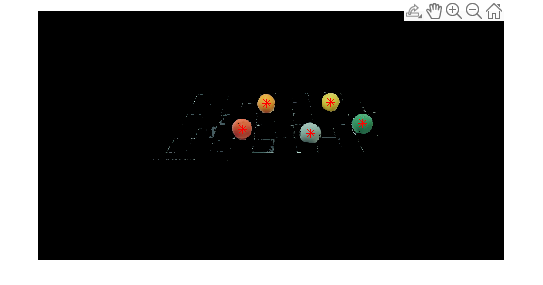

clear 
clc
close all
% cam = Camera();
maskPts = [289, 850, 881, 180;
           206, 206, 392, 389];
    try
    
%     pose = cam.getCameraPose();
    %disp("T_img_check");
    %disp(cam.cam_pose);
    try
                disp("Put Ball On");
                pause;      
     end
%       image = cam.getImage();
     image = imread("ALLCOLORS2.png");
% %        image = cam.getImage();
      mask = zeros(size(image, 1), size(image, 2));
      mask = poly2mask(maskPts(1, :), maskPts(2, :), size(image, 1), size(image, 2));
      mask = logical(mask);
      maskedImage = image;
      maskedImage(repmat(~mask, [1, 1, size(image, 3)])) = 0;
      ball = createMask(maskedImage); 
      filledBall = imfill(ball, 'holes');

      ball = logical(ball);
      ballMaskedImage = image;
      
      ballMaskedImage(repmat(~ball, [1, 1, size(image,3)])) = 0;

      L = bwlabel(filledBall);
      stats = regionprops(L, 'Centroid', 'Area');
      validCircles = [];
      for i = 1:length(stats)
        centroid = stats(i).Centroid;
        area = stats(i).Area;
        if area > 1000
            disp(centroid);
            disp(area);
            validCircles = [validCircles; centroid, area];
        end



      end
    colorOfBall = cell(length(validCircles), 1);
    ballColor = cell(length(validCircles), 1);
    for i = 1:length(validCircles)
        hsvImage = rgb2hsv(image);
        [x, y] = meshgrid(1:size(hsvImage, 2), 1:size(hsvImage, 1));
        
        % Extract circle parameters for the current iteration
        centerX = validCircles(i, 1);
        centerY = validCircles(i, 2);
        radius = sqrt(validCircles(i, 3)/pi)/2;
        
        % Create a binary mask for the circle
        maskColor = zeros(size(hsvImage, 1), size(hsvImage, 2));
        maskColor = ((x - centerX).^2 + (y - centerY).^2) <= radius^2;
        maskColor = logical(maskColor);
        % Extract the ROI from the hsvImage
        roiHue = hsvImage(:, :, 1);
        roiSaturation = hsvImage(:, :, 2);
        roiValue = hsvImage(:, :, 3);
        
        roiHue(~maskColor) = 0;
        roiSaturation(~maskColor) = 0;
        roiValue(~maskColor) = 0;
        
        % Calculate the average Hue, Saturation, and Value inside the ROI
        average_hue = mean(roiHue(maskColor));
        average_saturation = mean(roiSaturation(maskColor));
        average_value = mean(roiValue(maskColor));
        
        % Display the average HSV values and debug info
        fprintf('Circle %d: centerX = %d, centerY = %d, radius = %d\n', i, centerX, centerY, radius);
        fprintf('Average HSV for Circle %d: Hue = %.2f, Saturation = %.2f, Value = %.2f\n', i, average_hue, average_saturation, average_value);
        
        % You can also convert the average HSV values back to RGB for visualization.
        average_rgb = hsv2rgb([average_hue, average_saturation, average_value]);
        if(average_hue > 0.4)
            ballColorInput = sprintf('Ball %d Color: Green', i);
            ballColor{i} = sprintf('green');
        else
            ballColorInput = sprintf('Ball %d Color: Yellow', i);
            ballColor{i} = sprintf('yellow');
        end
        colorOfBall{i} = ballColorInput;
        
        
        fprintf('Average RGB for Circle %d: R = %.2f, G = %.2f, B = %.2f\n', i, average_rgb(1), average_rgb(2), average_rgb(3));
    end

     

      BallOverlayed = image;
      if(length(validCircles) > 1)
        for i = 1:length(validCircles)
            BallOverlayed = insertObjectAnnotation(BallOverlayed, "circle", [validCircles(i, 1:2) sqrt(validCircles(i, 3)/pi)], colorOfBall(i),  LineWidth = 2, TextBoxOpacity=0, TextColor = ballColor(i), Color=ballColor(i));
        end
      else
                  BallOverlayed = insertObjectAnnotation(BallOverlayed, "circle", [validCircles(1, 1:2) sqrt(validCircles(1, 3)/pi)], colorOfBall(1),  LineWidth = 2, TextBoxOpacity=0, TextColor = ballColor(1), Color=ballColor(1));
      end
      
%       gray_image = im2gray(maskedImage);
%       bw = gray_image < 50;
%       stats = regionprops("table", bw, "Centroid", ...
%           "MajorAxisLength", "MinorAxisLength");

      %imageWithMask = insertObjectMask(image, maskedImage);
      
      figure(1)
      imshow(ballMaskedImage);
      
      hold on
        plot(validCircles(:,1), validCircles(:,2), 'r*')
      hold off

      catch exception
    getReport(exception)
    disp('Exited on error, clean shutdown');
end